## Feature Manipulation Experiment 3

**In this notebook we will create a SHH containing to HHs (HH1 and HH3), where each HH has different solvers. **

**HH1 we already have it from the previous experiments and it contains LPT and SPT as solvers. **

**HH3 we will create an it will contain MPA and LPA as solvers. **

**The SHH should be able to solve correctly a set of four instances: **

**I1: An instance where LPT outperforms the other three heuristics.**

**I2: An instance where SPT outperforms the other three heuristics.**

**I3: An instance where MPA outperforms the other three heuristics.**

**I5: An instance where LPA outperforms the other three heuristics.**

**The first three instances we already have them, the fourth instance we will call it I5 because we already have a I4 from Experiment 3. **

**The files needed for this notebook to run are: **

**FM_I1.mat, FM_I2.mat, FM_I3.mat, FM_I5.mat, LPT.mat, SPT.mat, MPA.mat, FM_HH1.mat, FM_HH1_multi.mat, FM_Exp3_Results.mat**

**CLEANING AND FOLDERS**

%First let's clean everything and add needed folders
clc
clear
close all

addpath(genpath('extended/Domains/JSSP')); % Adds JSSP functionality
addpath(genpath('extended/Utils')); % Adds assorted utilities

**LOADING FILES**

%Loading instance I1, I2, and I3
load("FM_I1.mat")
load("FM_I2.mat")
load("FM_I3.mat")

%For precaution let's reset the instances 
I1.reset
I2.reset
I3.reset
InstanceSet={I1 I2 I3};

%Loading heuristics
load('LPT.mat')
load('SPT.mat')
load('MPA.mat')

%Loading HH1
load('FM_HH1.mat')
load('FM_HH1_multi.mat')

%Loading results from Exp2 
load("FM_Exp2_Results.mat")

**INITIAL VISUALIZATION**

%Let's see our previous results
Results

Results = 7×5 cell array
    {0×0 double}    {["Instance 1"]}    {["Instance 2"]}    {["Instance 3"]}    {'Instance 4'}
    {["LPT"   ]}    {[          41]}    {[     41.0665]}    {[     72.4897]}    {[   48.1692]}
    {["SPT"   ]}    {[          61]}    {[     21.0665]}    {[     73.0239]}    {[   28.1692]}
    {["MPA"   ]}    {[          58]}    {[     41.0665]}    {[     33.0303]}    {[   48.1692]}
    {'HH_1'    }    {[          42]}    {[     21.0665]}    {[     73.0239]}    {[   50.8885]}
    {'HH_2'    }    {[          61]}    {[     21.0665]}    {[     33.0303]}    {[   28.1692]}
    {'SHH2'    }    {[          42]}    {[     21.0665]}    {[     33.0303]}    {[   28.1692]}


**We need to replace instance 4 for our new instance, and we need to create  LPA with the ruleBasedHH class so we can solve the other instances with it.**

**CREATING LPA **

fields=struct('nbRules',1,'selectedSolvers', [4]);
LPA=ruleBasedSelectionHH(fields);

**ADDING LPA TO THE RESULTS **

solvedInstances_LPA=LPA.solveInstanceSet(InstanceSet);

%cleaning and changing values
Results{6,1}=Results{5,1};
Results{6,2}=Results{5,1};
Results{6,3}=Results{5,1};
Results{6,4}=Results{5,1};
Results{2,5}='';
Results{3,5}='';
Results{4,5}='';
Results{5,5}='';
Results{6,1}='HH1';
Results{6,2}='';
Results{6,3}='';
Results{6,4}='';
Results{6,5}='';
Results{7,1}='HH3';
Results{7,2}='';
Results{7,3}='';
Results{7,4}='';
Results{7,5}='';
Results{8,1}='SHH3';

%adding the LPA results 
Results{1,5}='Instance 5';
Results{5,1}='LPA';
Results{5,2}=solvedInstances_LPA{1}.solution.makespan;
Results{5,3}=solvedInstances_LPA{2}.solution.makespan;
Results{5,4}=solvedInstances_LPA{3}.solution.makespan;
Results

Results = 8×5 cell array
    {0×0 double}    {["Instance 1"]}    {["Instance 2"]}    {["Instance 3"]}    {'Instance 5'}
    {["LPT"   ]}    {[          41]}    {[     41.0665]}    {[     72.4897]}    {0×0 char    }
    {["SPT"   ]}    {[          61]}    {[     21.0665]}    {[     73.0239]}    {0×0 char    }
    {["MPA"   ]}    {[          58]}    {[     41.0665]}    {[     33.0303]}    {0×0 char    }
    {'LPA'     }    {[          41]}    {[     41.0665]}    {[     72.4882]}    {0×0 char    }
    {'HH1'     }    {0×0 char      }    {0×0 char      }    {0×0 char      }    {0×0 char    }
    {'HH3'     }    {0×0 char      }    {0×0 char      }    {0×0 char      }    {0×0 char    }
    {'SHH3'    }    {0×0 double    }    {0×0 double    }    {0×0 double    }    {0×0 double  }


**FINDING THE FOURTH INSTANCE (I5)**

%Loading instance
load("FM_I5.mat")

%Adding instance to Instance Set
InstanceSet{4}=I5;

%solving with all solvers 
solvedInstances_LPT=LPT.solveInstanceSet(InstanceSet);
solvedInstances_SPT=SPT.solveInstanceSet(InstanceSet);
solvedInstances_MPA=MPA.solveInstanceSet(InstanceSet);
solvedInstances_LPA=LPA.solveInstanceSet(InstanceSet);
solvedInstances_HH1=FM_HH1.solveInstanceSet(InstanceSet);

%Adding results for instance 5
Results{2,5}=solvedInstances_LPT{4}.solution.makespan;
Results{3,5}=solvedInstances_SPT{4}.solution.makespan;
Results{4,5}=solvedInstances_MPA{4}.solution.makespan;
Results{5,5}=solvedInstances_LPA{4}.solution.makespan;

%Adding results from HH1
Results{6,2}=solvedInstances_HH1{1}.solution.makespan;
Results{6,3}=solvedInstances_HH1{2}.solution.makespan;
Results{6,4}=solvedInstances_HH1{3}.solution.makespan;
Results{6,5}=solvedInstances_HH1{4}.solution.makespan;
Results

Results = 8×5 cell array
    {0×0 double}    {["Instance 1"]}    {["Instance 2"]}    {["Instance 3"]}    {'Instance 5'}
    {["LPT"   ]}    {[          41]}    {[     41.0665]}    {[     72.4897]}    {[   40.0000]}
    {["SPT"   ]}    {[          61]}    {[     21.0665]}    {[     73.0239]}    {[   40.0000]}
    {["MPA"   ]}    {[          58]}    {[     41.0665]}    {[     33.0303]}    {[   40.0000]}
    {'LPA'     }    {[          41]}    {[     41.0665]}    {[     72.4882]}    {[   20.0000]}
    {'HH1'     }    {[          42]}    {[     21.0665]}    {[     73.0239]}    {[   40.0000]}
    {'HH3'     }    {0×0 char      }    {0×0 char      }    {0×0 char      }    {0×0 char    }
    {'SHH3'    }    {0×0 double    }    {0×0 double    }    {0×0 double    }    {0×0 double  }


**It looks like we found our instance, LPA solves it better than the other heuristics, and also HH1 only solves properly I1 and I2, now let's create HH3 to properly solve I3 and I5.**

**CREATING HH3**

%Creating a HH (HH3) with MPA and LPA as solvers

fields=struct('nbRules',2,'selectedSolvers',[3 4],'selectedFeatures',[1]);
FM_HH3=ruleBasedSelectionHH(fields);


%Now let's look at the features of I3 and I5
I3.getFeatureVector([1 2 3 4 5])

ans =     0.0751    0.0615    0.3064    0.4074    0.1250


I5.getFeatureVector([1 2 3 4 5])

ans =          0    0.4923    0.4015    0.2963    0.0417


**It looks like the second feature is the one with the most different values, let's try that**

**TESTING A HH3 MODEL**

%Creating and adding the model
HH3_model=[0.3 3;0.5 4];
FM_HH3.value=HH3_model;

%CHOOSING THE SECOND FEATURE
FM_HH3.featureIDs=2; 

%Testing the model
solvedInstances_HH3=FM_HH3.solveInstanceSet(InstanceSet);
Results{7,2}=solvedInstances_HH3{1}.solution.makespan;
Results{7,3}=solvedInstances_HH3{2}.solution.makespan;
Results{7,4}=solvedInstances_HH3{3}.solution.makespan;
Results{7,5}=solvedInstances_HH3{4}.solution.makespan;
Results

Results = 8×5 cell array
    {0×0 double}    {["Instance 1"]}    {["Instance 2"]}    {["Instance 3"]}    {'Instance 5'}
    {["LPT"   ]}    {[          41]}    {[     41.0665]}    {[     72.4897]}    {[   40.0000]}
    {["SPT"   ]}    {[          61]}    {[     21.0665]}    {[     73.0239]}    {[   40.0000]}
    {["MPA"   ]}    {[          58]}    {[     41.0665]}    {[     33.0303]}    {[   40.0000]}
    {'LPA'     }    {[          41]}    {[     41.0665]}    {[     72.4882]}    {[   20.0000]}
    {'HH1'     }    {[          42]}    {[     21.0665]}    {[     73.0239]}    {[   40.0000]}
    {'HH3'     }    {[          49]}    {[     41.0665]}    {[     33.0303]}    {[   20.0000]}
    {'SHH3'    }    {0×0 double    }    {0×0 double    }    {0×0 double    }    {0×0 double  }


**Now we have an HH3 able to solve properly I4 and I5, now we need to create a SHH model able to select between HH1 and HH3 to properly solve all 4 instances.**

**CREATING SHH3 **

%First let's create de multi version of HH3
props = struct('nbLayers',1,'nbRules',2, 'selectedSolvers',3:4, 'selectedFeatures', [2]); %parameters for the HH in the multi form containing LPT and SPT and the first feature
FM_HH3_multi=ruleBasedSelectionHHMulti(props); %Creating the HH with multiHH class

FM_HH3_multi.value = FM_HH3.value; %copying the model of the HH

%Creating SHH3
props = struct('nbLayers',2,'selectedSolvers',1:2,...
                 'nbRules',3,'innerHHs',[FM_HH1_multi FM_HH3_multi],'selectedFeatures', [3]);
FM_SHH3=ruleBasedSelectionHHMulti(props);

**FINDING A MODEL FOR SHH3**

%Let's look at the features of all 4 instances
I1.getFeatureVector([1 2 3 4 5])

ans =     0.2812    0.4380    0.5413    0.6667    0.2500


I2.getFeatureVector([1 2 3 4 5])

ans =     0.0749    0.1805    0.1765    0.4074    0.1250


I3.getFeatureVector([1 2 3 4 5])

ans =     0.0751    0.0615    0.3064    0.4074    0.1250


I5.getFeatureVector([1 2 3 4 5])

ans =          0    0.4923    0.4015    0.2963    0.0417


**It looks like the feature 3 is the one where all instances have a different initial value. Let's try it: **

SHH3_model=[0.53 1; 0.35 1; 0.4 2 ];
FM_SHH3.value=SHH3_model;
solvedInstanceSet_SHH3=FM_SHH3.solveInstanceSet(InstanceSet);
Results{8,2}=solvedInstanceSet_SHH3{1}.solution.makespan;
Results{8,3}=solvedInstanceSet_SHH3{2}.solution.makespan;
Results{8,4}=solvedInstanceSet_SHH3{3}.solution.makespan;
Results{8,5}=solvedInstanceSet_SHH3{4}.solution.makespan;
Results

Results = 8×5 cell array
    {0×0 double}    {["Instance 1"]}    {["Instance 2"]}    {["Instance 3"]}    {'Instance 5'}
    {["LPT"   ]}    {[          41]}    {[     41.0665]}    {[     72.4897]}    {[   40.0000]}
    {["SPT"   ]}    {[          61]}    {[     21.0665]}    {[     73.0239]}    {[   40.0000]}
    {["MPA"   ]}    {[          58]}    {[     41.0665]}    {[     33.0303]}    {[   40.0000]}
    {'LPA'     }    {[          41]}    {[     41.0665]}    {[     72.4882]}    {[   20.0000]}
    {'HH1'     }    {[          42]}    {[     21.0665]}    {[     73.0239]}    {[   40.0000]}
    {'HH3'     }    {[          49]}    {[     41.0665]}    {[     33.0303]}    {[   20.0000]}
    {'SHH3'    }    {[          42]}    {[     21.0665]}    {[     43.0250]}    {[   20.0000]}


**So far the problem is that the instance 1 and instance 3 have similar ending feature values, we need a second feature that help us make the tie breaker between those two, it looks like feature 4 is going to help, let's try: **

**TRYING A MODEL WITH TWO FEATURES**

%Creating SHH3
props = struct('nbLayers',2,'selectedSolvers',1:2,...
                 'nbRules',3,'innerHHs',[FM_HH1_multi FM_HH3_multi],'selectedFeatures', [3 2]);
FM_SHH3=ruleBasedSelectionHHMulti(props);


SHH3_model=[0.53 0.43 1; 0.35 0.2 1; 0.5 0.2 2; 0.3 0.2 2; 0.4 0.5 2];
FM_SHH3.value=SHH3_model;
solvedInstanceSet_SHH3=FM_SHH3.solveInstanceSet(InstanceSet);
Results{8,2}=solvedInstanceSet_SHH3{1}.solution.makespan;
Results{8,3}=solvedInstanceSet_SHH3{2}.solution.makespan;
Results{8,4}=solvedInstanceSet_SHH3{3}.solution.makespan;
Results{8,5}=solvedInstanceSet_SHH3{4}.solution.makespan;
Results

Results = 8×5 cell array
    {0×0 double}    {["Instance 1"]}    {["Instance 2"]}    {["Instance 3"]}    {'Instance 5'}
    {["LPT"   ]}    {[          41]}    {[     41.0665]}    {[     72.4897]}    {[   40.0000]}
    {["SPT"   ]}    {[          61]}    {[     21.0665]}    {[     73.0239]}    {[   40.0000]}
    {["MPA"   ]}    {[          58]}    {[     41.0665]}    {[     33.0303]}    {[   40.0000]}
    {'LPA'     }    {[          41]}    {[     41.0665]}    {[     72.4882]}    {[   20.0000]}
    {'HH1'     }    {[          42]}    {[     21.0665]}    {[     73.0239]}    {[   40.0000]}
    {'HH3'     }    {[          49]}    {[     41.0665]}    {[     33.0303]}    {[   20.0000]}
    {'SHH3'    }    {[          42]}    {[     21.0665]}    {[     33.0303]}    {[   20.0000]}


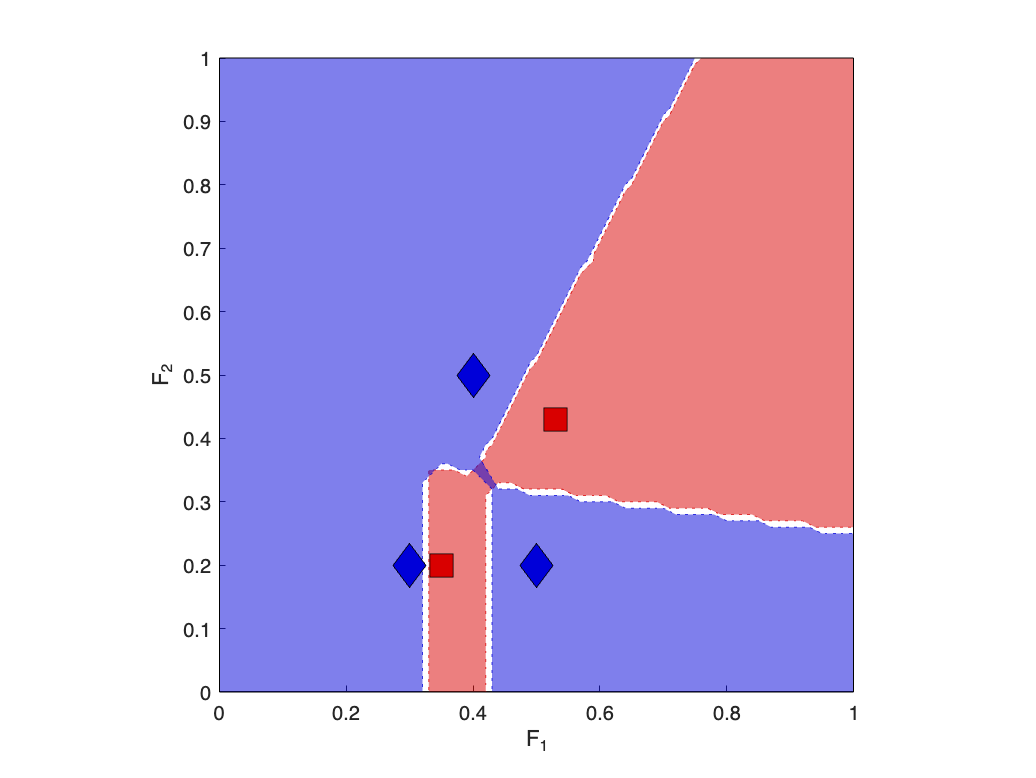

ans =     0.3365    0.6488


FM_SHH3.plotZones(0:0.01:1,1,[1 2],1)

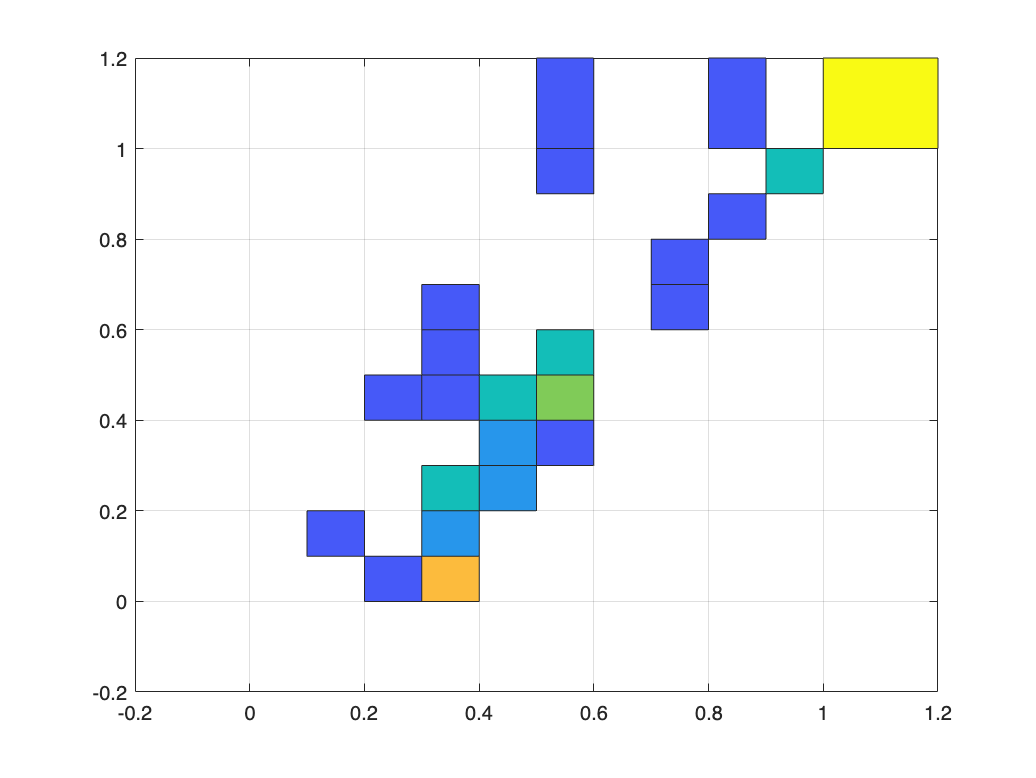

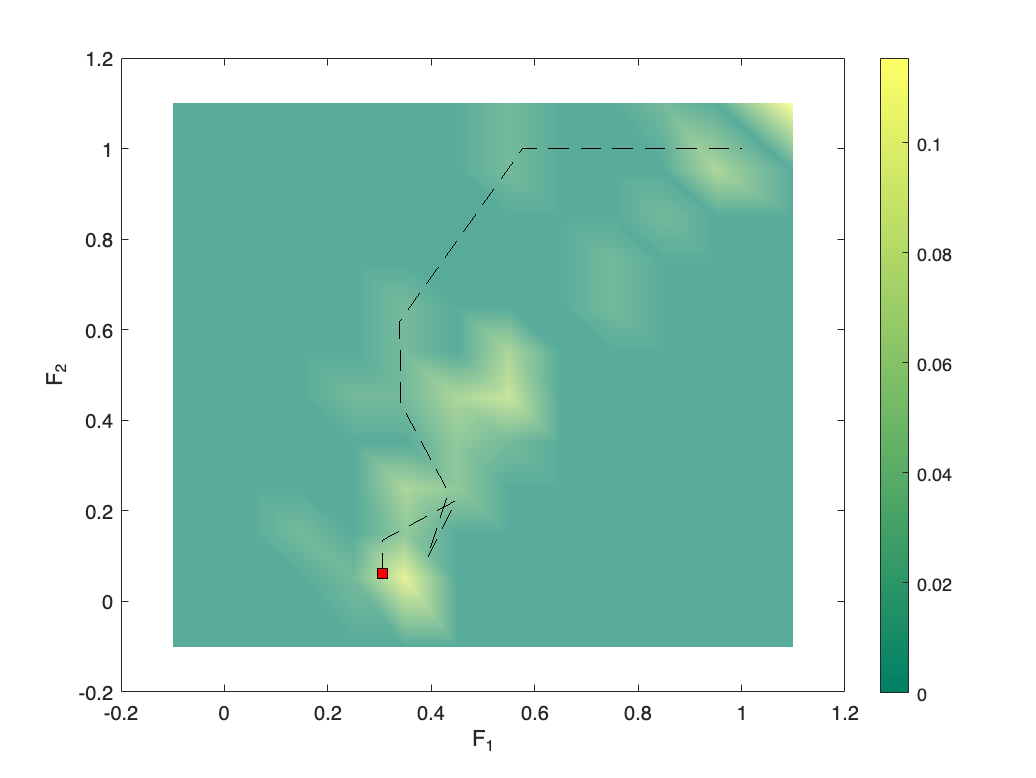

ans =   Surface with properties:

       EdgeColor: 'none'
       LineStyle: '-'
       FaceColor: 'interp'
    FaceLighting: 'flat'
       FaceAlpha: 0.6500
           XData: [-0.1000 0.0500 0.1500 0.2500 0.3500 0.4500 0.5500 0.6500 0.7500 0.8500 0.9500 1.1000]
           YData: [-0.1000 0.0500 0.1500 0.2500 0.3500 0.4500 0.5500 0.6500 0.7500 0.8500 0.9500 1.1000]
           ZData: [12×12 double]
           CData: [12×12 double]

  Show all properties


FM_SHH3.plotFeatureMap(InstanceSet,"full",struct('features',[1 2]),true,3)

**At the end we needed five rules to create the SHH we wanted. **

save('FM_SHH3','FM_SHH3')
save('FM_Exp3_Results','Results')
save('FM_HH3','FM_HH3')
save('FM_HH3_multi','FM_HH3_multi')
save('LPA','LPA')